## Setup the Virtual Simulation Environment

[**Instructions to setup RoboCup ARM provided virtual machine**](https://drive.google.com/file/d/1w9tBy3DKmZBKEfOqOFUXcT8hcQig6sNS/view)** (Appendix A)**

Follow the instructions above to setup the MathWorks provided Virtual Machine in your computer.

Find and open one of the environments for the RoboCup ARM Challenge. Note that there is more than on environment provided to ilustrate how objects in the environments are subject to changing positions and orientations based on the challenge instructions. 

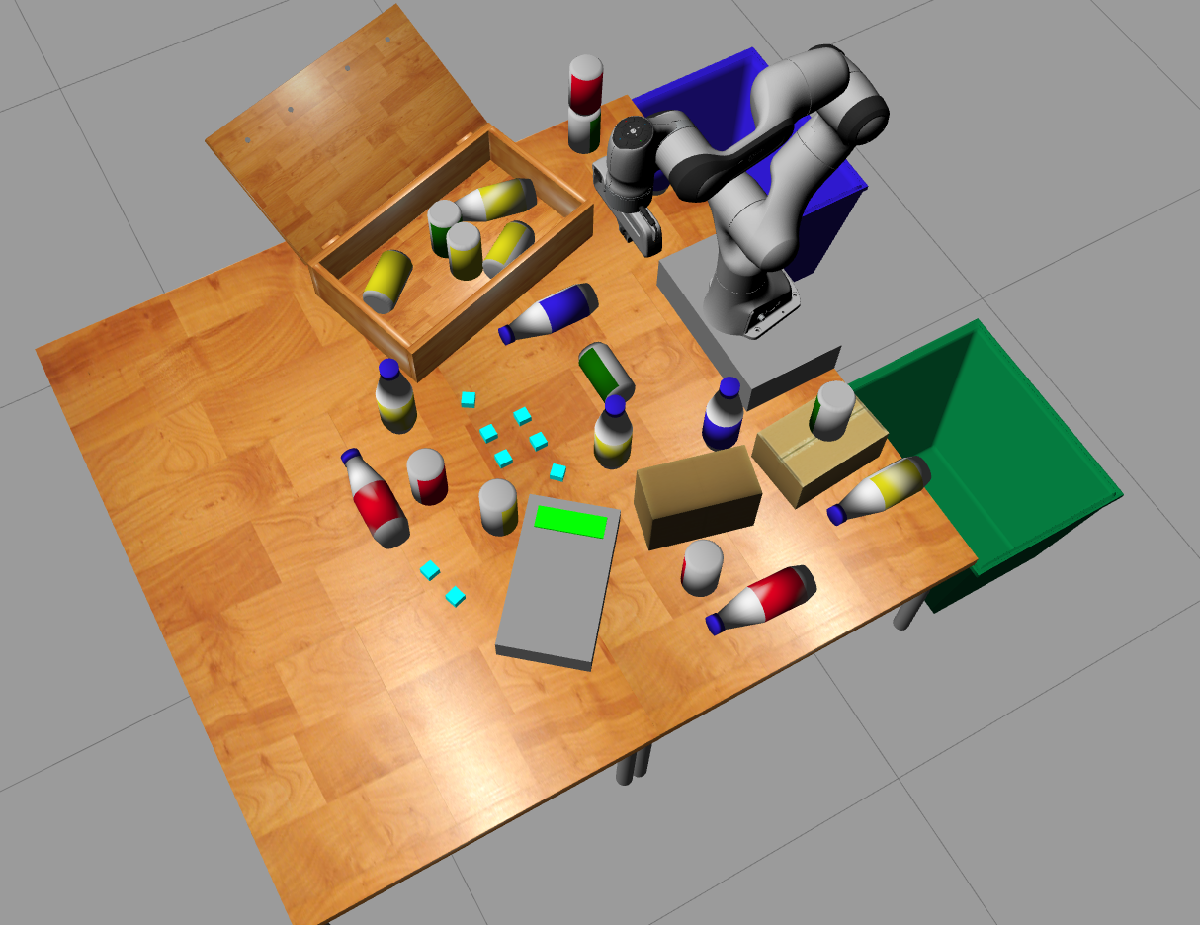

#### Connect MATLAB to Gazebo using the ROS Toolbox

Start a ROS node from MATLAB to interact with the Gazebo environment. For more information on interaction with the ROS ecosystem from MATLAB visit [Getting Started with ROS Toolbox](https://www.mathworks.com/help/ros/getting-started-with-ros-toolbox.html).

If you are having trouble with this step, or if you are waiting a long time for the nodes to communicate, try using the commented code in line 4. The IP address to be specified is the wireless network adapter address.

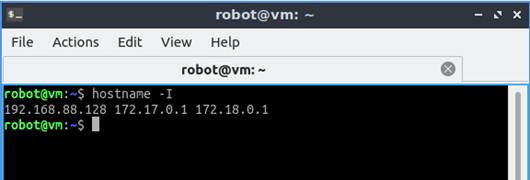

rosIP = "localhost"; % Change IP address!!    % IP address of ROS enabled machine  
rosshutdown; % shut down existing connection to ROS

Shutting down global node /matlab_global_node_65338 with NodeURI http://rdp-Altos-P10-F8:45497/ and MasterURI http://localhost:11311.


rosinit(rosIP,11311);

Initializing global node /matlab_global_node_95104 with NodeURI http://rdp-Altos-P10-F8:46439/ and MasterURI http://localhost:11311.


% rosinit(rosIP,'NodeHost','192.168.68.120') % Try specifying node host IP in case that there are multiple network adapters

## Initialize Robot and Start Simulator

#### Set initial robot configuration

setInitialConfig_franka; % DO NOT MODIFY

#### Unpause GAZEBO physics.

Unpausing the Gazebo simulation is necessary to make sure the environment physics are active.

physicsClient = rossvcclient('gazebo/unpause_physics'); %unpause physics
physicsResp = call(physicsClient,'Timeout',3); %send default message

## Control Gripper Using ROS Action Client

[gripAct,gripGoal] = rosactionclient('/franka_gripper/gripper_action');
gripperCommand = rosmessage(gripAct);

gripperCommand.Command.Position = 3.91; %0 is fully closed, 4 is fully open
gripperCommand.Command.MaxEffort = 50; %N
gripperCommand.Command.Position = gripperCommand.Command.Position / 100;
gripGoal.Command = gripperCommand.Command;
% waitForServer(gripAct); % Can use this function if concerned with missed
% goals but generally it should work correctly.
sendGoal(gripAct,gripGoal)

## Control Gripper Position using ROS Action Client

#### Setup ROS message and publisher for Joint Control

jointMess = rosmessage("geometry_msgs/PoseStamped");
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");

#### Define Gripper Pose

This section defines the desired gripper location and orientation using a homogeneous transformation. [Learn more about homogeneous transform here.](https://www.mathworks.com/help/robotics/coordinate-system-transformations.html)

To reset pose to approximate initial configuration, set the gripper location to [0.35, 0.0001, 0.5] and orientation to [-pi. -0.01,0]

gripperX = 0.33;
gripperY = 0.08;
gripperZ = 0.85;
gripperTranslation = [gripperX gripperY gripperZ];
gripperRotationX = -pi; % radians
gripperRotationY = -0.01; % radians
gripperRotationZ = 0; % radians

jointMess.Pose.Position.X = gripperX;
jointMess.Pose.Position.Y = gripperY;
jointMess.Pose.Position.Z = gripperZ;
quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
jointMess.Pose.Orientation.W = quat(1);
jointMess.Pose.Orientation.X = quat(2);
jointMess.Pose.Orientation.Y = quat(3);
jointMess.Pose.Orientation.Z = quat(4);
send(jointPub,jointMess);

## **Effective use of RGB camera**

Data processed from the depth camera leads to successful classification of at least one bottle or can.

### Using a YoloV2 model pre-trained on two classes of objects (bottle, can)

disp('*-----Object Detection and Classification-----*')

*-----Object Detection and Classification-----*



% Getting Yolov2 model
% Load deep learning model for object detection
temp = load('exampleHelperYolo2DetectorROSGazebo.mat');
DetectorModel = temp.detectorYolo2;

% Detect parts
% This function detects parts using a pre-trained deep learning model.

% Read image from simulated Gazebo camera
rgbImg = getRGBImage

Getting RGB Image


rgbImg = 480×640×3 uint8 array
rgbImg(:,:,1) =

   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   183   223   231   233   233   233   234   233   232   231   231   232   231   231   230   229   228   227   225   226   227   228   228   229   230   231   231   233   234   236   236   236   236   236   236   237   238   239   238   238   238   236   234   234   234   233   233   235   236   237   237   237   238   238   238   238   238   238   239   240   242   243   240   237   234   233   233   234   235   235   234   234   236   238   239   239   240   240   240   241   242   241   239   237   233   228   227   227   226   227   229   230   231   232   234   235   237   239   240   241   243   244   242   240   239   240   239   239   238   2

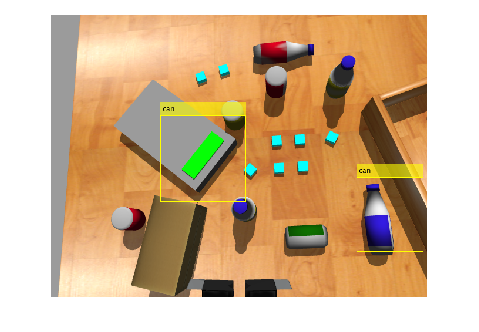


% Detect parts and show labels
[bboxes,~,labels] = detect(DetectorModel,rgbImg);
if ~isempty(labels)
    labeledImg = insertObjectAnnotation(rgbImg,'Rectangle',bboxes,cellstr(labels));
    imshow(labeledImg);            
end

### Detect Objects Using Pretrained YOLO v2 Object Detector

name = "tiny-yolov2-coco";
% Create YOLO v2 object detector by using the pretrained YOLO v2 network.
detector = yolov2ObjectDetector(name);
% Display and inspect the properties of the YOLO v2 object detector.matlab:helpPopup yolov2ObjectDetector
disp(detector)

  yolov2ObjectDetector with properties:

            ModelName: 'tiny-yolov2-coco'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [416 416]
          AnchorBoxes: [5×2 double]
           ClassNames: [person    bicycle    car    motorbike    …    ]



% Read image from simulated Gazebo camera
img = getRGBImage

Getting RGB Image


img = 480×640×3 uint8 array
img(:,:,1) =

   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   197   224   230   229   229   228   228   228   230   231   231   230   230   229   227   225   223   221   221   223   224   225   225   224   224   224   225   227   228   227   227   226   226   227   227   227   228   229   230   230   231   231   231   232   231   228   226   224   225   227   229   230   229   228   227   227   227   226   225   225   225   226   227   228   228   228   229   229   228   226   226   227   228   229   229   230   230   231   232   232   232   231   229   225   221   216   214   216   218   220   221   220   219   218   217   216   215   2

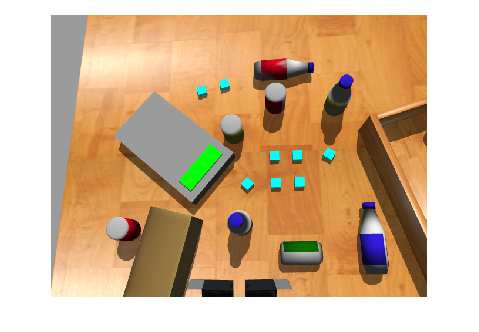

% Detect objects in image by using the pretrained YOLO v2 object detector.
[bboxes,scores,labels] = detect(detector,img);
% Display the detection results.
detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure
imshow(detectedImg)

% use this to calculate and copy pase configurations
pose=getCurrentRobotJConfig;
disp(pose)

    0.5809   -0.3234   -0.1894   -1.0723   -0.1070    1.0437    1.1264



## Pick-Place in Static Region

setInitialConfig_franka; % DO NOT MODIFY
jointMess = rosmessage("geometry_msgs/PoseStamped");
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");
pause(2);
[gripAct,gripGoal] = rosactionclient('/franka_gripper/gripper_action');
gripperCommand = rosmessage(gripAct);

### Red Horizontal Bottle

setInitialConfig_franka; % DO NOT MODIFY

% % Pre-defined poses
% poses = {[0.31, 0.64, 0.1]};
% % Pre-defined configurations w.r.t to Pre-defined poses
% goalConfigStaticArray={[1.0178    0.7159    0.1081   -1.6379   -0.0520    2.4146    1.8929]};
% % Execute
% goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
% 
% 
% 
% gripperGoal(3.9, gripAct, gripGoal, gripperCommand)
% 
% 
% 
% % Pre-defined poses
% poses = {[0.31, 0.64, -0.07]};
% % Pre-defined configurations w.r.t to Pre-defined poses
% goalConfigStaticArray={[1.1033    1.0620    0.0129   -1.4944    0.0365    2.6233    1.8386]};
% % Execute
% goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
% 
% 
% 
% gripperGoal(3.3, gripAct, gripGoal, gripperCommand)
% 
% 
% % Pre-defined poses
% poses = {[0.31, 0.64, 0.1]};
% % Pre-defined configurations w.r.t to Pre-defined poses
% goalConfigStaticArray={[1.0178    0.7159    0.1081   -1.6379   -0.0520    2.4146    1.8929]};
% % Execute
% goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
% 
% 
% setInitialConfig_franka;
% 
% 
% % Pre-defined poses
% poses = {[-0.4, -0.5, 0.4]};
% % Pre-defined configurations w.r.t to Pre-defined poses
% goalConfigStaticArray={[-0.2114   -1.1348   -1.3451   -1.6423   -1.1436    1.4808   -0.7985]};
% % Execute
% goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
% 
% 
% gripperGoal(3.9, gripAct, gripGoal, gripperCommand)

% % Pre-defined poses
% poses = {[0.4, 0.52, 0.1]};
% % Pre-defined configurations w.r.t to Pre-defined poses
% goalConfigStaticArray={[-1.1645   -1.3226   1.7797   -1.7631    1.3783    1.8591    1.0231]};
% % Execute
% goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
% 
% 
% 
% gripperGoal(3.9, gripAct, gripGoal, gripperCommand)
% 
% 
% 
% % Pre-defined poses
% poses = {[0.4, 0.52, -0.07]};
% % Pre-defined configurations w.r.t to Pre-defined poses
% goalConfigStaticArray={[-1.2147    -1.5367    1.9067    -1.6941    1.5811    1.9212    1.0184]};
% % Execute
% goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
% 
% 
% gripperGoal(3.3, gripAct, gripGoal, gripperCommand)
% 
% 
% % Pre-defined poses
% poses = {[0.4, 0.52, 0.1]};
% % Pre-defined configurations w.r.t to Pre-defined poses
% goalConfigStaticArray={[-1.1645   -1.3226   1.7797   -1.7631    1.3783    1.8591    1.0231]};
% % Execute
% goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
% 
% 
% setInitialConfig_franka;
% 
% 
% % Pre-defined poses
% poses = {[-0.4, 0.5, 0.4]};
% % Pre-defined configurations w.r.t to Pre-defined poses
% goalConfigStaticArray={[-0.2114   -1.1348   -1.3451   -1.6423   -1.1436    1.4808   -0.7985]};
% % Execute
% goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
% 
% 
% gripperGoal(3.9, gripAct, gripGoal, gripperCommand)

Routine

setInitialConfig_franka;

gripperGoal(3.99, gripAct, gripGoal, gripperCommand)
c_pose= [0.4; 0; 0.4];
g_pose= [0.31; 0.64; 0.1];
smoothen_motion(c_pose,g_pose,0.06)

Qi =     0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.4000    0.3999    0.3999    0.3999    0.3999    0.3998    0.3998    0.3998    0.3997    0.3996    0.3996    0.3995    0.3994    0.3994    0.3993    0.3992    0.3991    0.3989    0.3988    0.3987    0.3985    0.3984    0.3982    0.3981    0.3979    0.3977    0.3975    0.3973    0.3971    0.3969    0.3966    0.3964    0.3961    0.3959    0.3956    0.3953    0.3950    0.3947    0.3944    0.3940    0.3937    0.3933


T =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


Q =     0.4000         0    0.4000
    0.4000    0.0000    0.4000
    0.4000    0.0000    0.4000
    0.4000    0.0000    0.4000
    0.4000    0.0000    0.4000
    0.4000    0.0001    0.4000
    0.4000    0.0001    0.3999
    0.4000    0.0002    0.3999
    0.4000    0.0003    0.3999
    0.3999    0.0004    0.3998



c_pose=[0.31; 0.64; 0.1];
g_pose=[0.31; 0.64; -0.08];
smoothen_motion(c_pose,g_pose,0.01)

Qi =     0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100    0.3100


T =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


Q =     0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000
    0.3100    0.6400    0.1000


gripperGoal(3.3, gripAct, gripGoal, gripperCommand)
pause(2);
c_pose=[0.31; 0.64; -0.08];
g_pose=[0.31; 0.64; 0.1];
smoothen_motion(c_pose,g_pose,0.06)

c_pose=[0.31; 0.64; 0.1];
g_pose=[-0.4; 0.4; 0.4];
smoothen_motion(c_pose,g_pose,0.09)


c_pose=[-0.4; 0.4; 0.4];
g_pose=[-0.4; -0.5; 0.4];
smoothen_motion(c_pose,g_pose,0.09)

gripperGoal(3.99, gripAct, gripGoal, gripperCommand)



Trajectory

gripperGoal(3.9, gripAct, gripGoal, gripperCommand)

i_poses = [0.31; 0.64; 0.1];
f_poses = [0.31; 0.64; -0.07];
speed = 0.01;
t = 0.5 + max(abs(i_poses - f_poses))/speed;

[Qi,T] = get_polynomial_trajectory(i_poses(1), f_poses(1), t, 0.05)
jointMess.Pose.Position.Z = pz;
send(jointPub,jointMess);
 Q = zeros(length(f_poses), length(T));
    Q(1,:) = Qi;
    for i=2:length(f_poses)
        [Qi,T] = get_polynomial_trajectory(i_poses(i), f_poses(i), t, 0.05);
        Q(i,:) = Qi;
    end
    Q = Q'
for j =1:length(Q)
  jointMess.Pose.Position.X = Q(j,1);
  jointMess.Pose.Position.Y = Q(j,2);
  jointMess.Pose.Position.Z = Q(j,3);
  send(jointPub,jointMess);
  pause(0.05)
end  


function smoothen_motion(c_pose, g_pose, speed)
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");
jointMess = rosmessage("geometry_msgs/PoseStamped");
i_poses = c_pose;
f_poses = g_pose;
t = 0.5 + max(abs(i_poses - f_poses))/speed;
[Qi,T] = get_polynomial_trajectory(i_poses(1), f_poses(1), t, 0.05)
%jointMess.Pose.Position.Z = pz;
%send(jointPub,jointMess);
 Q = zeros(length(f_poses), length(T));
    Q(1,:) = Qi;
    for i=2:length(f_poses)
        [Qi,T] = get_polynomial_trajectory(i_poses(i), f_poses(i), t, 0.05);
        Q(i,:) = Qi;
    end
    Q = Q'
for j =1:length(Q)
  jointMess.Pose.Position.X = Q(j,1);
  jointMess.Pose.Position.Y = Q(j,2);
  jointMess.Pose.Position.Z = Q(j,3);
  send(jointPub,jointMess);
  pause(0.05)
end  

end

function goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
    % Iterate over the array of arrays
    for i = 1:numel(poses)
        gripperX = poses{i}(1);
        gripperY = poses{i}(2);
        gripperZ = poses{i}(3);
        gripperTranslation = [gripperX gripperY gripperZ];
        gripperRotationX = -pi; % radians
        gripperRotationY = -0.01; % radians
        gripperRotationZ = 0; % radians
        
        jointMess.Pose.Position.X = gripperX;
        jointMess.Pose.Position.Y = gripperY;
        jointMess.Pose.Position.Z = gripperZ;
        quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
        jointMess.Pose.Orientation.W = quat(1);
        jointMess.Pose.Orientation.X = quat(2);
        jointMess.Pose.Orientation.Y = quat(3);
        jointMess.Pose.Orientation.Z = quat(4);
        send(jointPub,jointMess);
    
        % Wait until the robot reaches destination
        pause(1.0);        % this pause is needed to start asking for movement status
        isAway = true;
        disp('Waiting until robot reaches the desired configuration');
        while isAway
            isAway = checkTargetAchieved(goalConfigStaticArray{i});
            pause(1);
       end
        fprintf('Goal %d Achieved',i);
    end
end

function gripperGoal(position, gripAct, gripGoal, gripperCommand)
    gripperCommand.Command.Position = position; %0 is fully closed, 4 is fully open
    gripperCommand.Command.MaxEffort = 30; %N
    gripperCommand.Command.Position = gripperCommand.Command.Position / 100;
    gripGoal.Command = gripperCommand.Command;
    waitForServer(gripAct); % Can use this function if concerned with missed
    % goals but generally it should work correctly.
    sendGoal(gripAct,gripGoal)
    pause(5)
end

## **Function Definitions**

function JConfig = getCurrentRobotJConfig
    jMsg = receive(rossubscriber('/joint_states'));
    JConfig =  jMsg.Position(1:7)';
end

% Receive Camera Image Using ROS Subscriber
function rgbImg = getRGBImage
    disp("Getting RGB Image")
    rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
    curImage = receive(rgbImgSub,3);
    pause(1)
    rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
end

% Receive Depth Image Using ROS Subscriber
function depthImg = getDepthImage
    disp("Getting Depth Image")
    rgbDptSub = rossubscriber('/camera/depth/image_raw');
    curDepth = receive(rgbDptSub,3);
    depthImg = readImage(rgbDptSub.LatestMessage); 
end

% Check if target achieved
function isAway = checkTargetAchieved(goalConfig)
    isAway = true;
    jointCurrent=(getCurrentRobotJConfig);
    if all(abs((jointCurrent-(goalConfig)))<0.1)     
        isAway=false; % goal achieved       
    end           
end